clc % clear command window
clear all % clear workspace

1. Supply path to the toolkit's "model_code" directory to "cfg" structure, and add the "common" subfolder to the MATLAB path. Also specify the general directory where results will be saved. 

% Add paths to relevant functions
cfg.model_dir = '/Shared/boeslab/Users/jcgriffis/ibb_modeling_toolkit/model_code'; % path to toolkit
addpath(genpath(fullfile(cfg.model_dir, 'common'))); % add common folder to path

% Specify output directory (Note - output folders for specific analyses will be created in this directory)
out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results';

2. To perform a disconnectome analysis, specify that the modality is "other", and load a table containing the coordinates of each region in the connectome, as shown in the output below.

% Specify data modality and supply brain mask
cfg.modality = 'other'; % predictor modality - 'lesion' or 'other' 
load('/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/parcel_table.mat');

    RegionID    RegionName     X      Y      Z     NetworkID
    ________    __________    ___    ___    ___    _________

       1        "LH_Vis_1"    -24    -52     -8        1    
       2        "LH_Vis_2"    -25    -76    -13        1    
       3        "LH_Vis_3"    -45    -68     -7        1    
       4        "LH_Vis_4"    -10    -66     -3        1    
       5        "LH_Vis_5"    -27    -94    -11        1    
       6        "LH_Vis_6"    -14    -44     -2        1    
       7        "LH_Vis_7"     -6    -92     -3        1    
       8        "LH_Vis_8"    -47    -69     11        1    



cfg.parcel_table = parcel_table;
head(cfg.parcel_table);

3. Specify general modeling options.

- cfg.model_spec - the type of model you want to fit. To run a PLSR model, set to 'plsr'.

- cfg.fit_explanatory_model - flag indicating whether you want to fit a model to the full dataset to test significance of model coefficients. For inferential (e.g., lesion-symptom mapping) analyses, turn this on. Note that the model is explanatory, not predictive. 

- cfg.optimize_hyperparams - flag indicating whether you want to use cross-validation to optimize model hyper-parameters. For multivariate models, this is recommended.

- cfg.cross_validation - flag indicating whether you want to use cross-validation to estimate predictive performance and out-of-sample generalization. If hyper-parameter optimization is selected, then this will perform nested cross-validation. For predictive analyses, turn this on. Note that significance testing is not performed on model coefficients/maps. 

- cfg.bootstrap - flag indicating whether you want to use bootstrapping to estimate statistical significance of model coefficients and/or to estimate confidence intervals for multivariate explanatory models. Recommended if fitting multivariate explanatory model.

- cfg.permutation - flag indicating whether you want to use permutation testing to estimate statistical significance of model fit and/or model coefficients. Recommended.

These options will be used to initialize an analysis with default parameters for the selected options by supplying the cfg structure as an input to the function get_default_model_cfg(), which automatically populates the cfg structure with default settings for the specified modeling options, and returns the populated cfg structure. 

% Specify general modeling options
cfg.model_spec = 'plsr'; % model to fit
cfg.fit_explanatory_model = 1; % fit explanatory model to full dataset 
cfg.optimize_hyperparams = 1; % use cross-validation to optimize model hyperparameters
cfg.cross_validation = 1; % use cross-validation to estimate out-of-sample predictive performance
cfg.bootstrap = 1; % use bootstrap resampling for significance testing of coefficients
cfg.permutation = 1; % use permutation testing for significance testing of model fit (and/or coefficients)

% Initialize cfg file with default settings given general modeling options
cfg = get_default_model_cfg(cfg); 

Analysis type is other - setting defaults for non-lesion analysis


4. Specify paths to behavioral and lesion data, and load and format data into predictor matrix and response array. The behavioral CSV file should include a "study_id" column containing patient IDs and a second column containing behavioal scores. Also specify the path to the directory containing the disconnection files. Disconnection files for all patients should be in the same folder. Note: IDs in "study_id" column must match file prefixes for disconnection data - e.g., if the "study_id" for patient 1 is "0001", then their disconnection file should be "0001.txt" or "0001.csv".

The function get_and_format_discon_data() adds several fields to the cfg structure: 

- cfg.X - subject-by-voxel lesion predictor matrix 

- cfg.Y - subject-by-1 array of behavioral scores

- cfg.include_subs - string array of subject IDs that had non-missing behavioral data and that were included in the analysis.

- cfg.include_inds - indices of included subjects in original ID array

% Specify path to CSV containing study IDs and behavioral scores
beh_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/test_data.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify directory containing connectivity data and indicate whether patients are registry patients
conn_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Disconnection_Matrices'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices
% Note: outputs are stored as fields in cfg structure 
cfg = get_and_format_matrix_data(beh_csv, id_col, beh_col, registry_flag, conn_dir, cfg);

All subjects with behavioral data have matrix files, N=282 patients will be included


% Invert behavioral scores so that more positive values -> worse performance 
cfg.Y = cfg.Y.*-1; 

5. Modify any default settings as relevant to the analysis. Here, we increase the minimum observation threshold to 5, the minimum frequency threshold to 10, set the number of bootstrap/permutation iterations, and set the number of folds and repeats used for hyper-parameter optimization and cross-validation. We also specify that we want to stratify train/test splits based on the outcome variable distribution. Lastly, we indicate that we want this to be a "stackable" prediction model, so we don't want to drop subjects that only have zero-valued predictor data, and we want to pre-generate train/test partitions before running any models. See the function get_default_model_cfg() for all default parameter values. 

% Customize analysis parameters

% Minimum data thresholds
cfg.min_obs = 5; % Minimum t-statisic for a voxel to count towards cfg.freq_thresh
cfg.freq_thresh = 10; % only include voxels with a t-statistic of at least abs(cfg.min_obs) in at least 10 patients

% Variable standardization
cfg.standardize = 0; % Standardize (1 - standardize X, 2 - standardize Y, 3 - standardize X & Y)

% Statistical significance testing 
cfg.boot.n_boot = 1000; % bootstrap iterations
cfg.perm.n_perm = 1000; % permutation iterations

% Hyper-parameter optimization
cfg.hp_opt.cv_type = 'KFold'; % Do K-fold cross-validation for hyper-parameter optimization
cfg.hp_opt.folds = 2; % 5-fold cross-validation
cfg.hp_opt.repeats = 5; % 5 repeats of 5-fold cross-validation

% Cross-validation
cfg.cv.cv_type = 'KFold'; % Do K-Fold cross-validation
cfg.cv.folds = 5; % 5-fold cross-validation
cfg.cv.repeats = 5; % 5 runs of 5-fold cross-validation
cfg.cv.permutation = 0; % Do permutation testing of cross-validation (turned off for this tutorial to save time)
cfg.cv.n_perm = 0; % do 0 permutations (at least 20 are recommended, this is the minimum to achieve p<0.05)
cfg.cv.stacked_model = 1; % Don't drop subjects with no non-zero predictor data 

% Stratification for cross-validation 
cfg.strat_var = cfg.Y; % stratification variable

6. Specify the specific folder where analysis results should be saved. Note - if the output folder specified in cfg.out_dir doesn't exist, it will be created automatically once the analysis is run.

% Specify output directory
cfg.out_dir = fullfile(out_dir, [cfg.model_spec '_' beh_col '_discon_d' num2str(cfg.dtlvc) '_s' num2str(cfg.standardize)]);

7. Supply the fully-specified cfg structure as input to the function fit_and_evaluate_model(), which executes the modeling analysis specified in the cfg structure. This returns a new structure, model_results, which contains the results of the modeling analysis along with the original cfg file (as a sub-structure) for reproducibility. This structure is saved by default in the folder specified by cfg.out_dir. If cross-validation was performed, a second structure named cv_results, which contains the results of the cross-validation analyses, will be saved in the file "cv_results.mat" within the output directory specified by cfg.out_dir. 

% fit model with CV hyperparameter optimization and selected significance testing
[model_results] = fit_and_evaluate_model(cfg);

model_results = struct with fields:
        has_data: [282×1 double]
           opt_k: 1
      hp_opt_mse: [84.4703 87.2527 95.1179 107.6856 112.6674]
              XS: [282×1 single]
           coeff: [1966×1 single]
          pred_y: [282×1 single]
       vip_score: [1966×1 single]
           obs_y: [282×1 double]
              r2: 0.3807
             mse: 81.1802
          beta_0: -44.0651
            perm: [1×1 struct]
            boot: [1×1 struct]
               X: [282×1966 single]
           X_ind: [1966×1 double]
        rng_seed: {[0]  'twister'}
             cfg: [1×1 struct]
    methods_text: 'Data were modeled using partial least squares regression (PLSR). Only predictors with at least 10 non-zero observations with absolute values greater than 5 were included in the analysis. N=282 observations were included in the analysis. An inferential model was fit to the full dataset.  Hyper-parameter optimization was performed to determine the  k parameter (number of PLS components)

8. View model results structure to evaluate model performance measures. The different fields contain different details about analysis parameters, data, and results.

- has_data - logical array of length n_subjects with values of 1 for all patients that were included in the analysis. If cfg.stacked_model were set to 0, then some patients could be dropped due to not having any data after removing voxels that met the minimum damage frequency threshold, and this can be used to identify which patients were dropped and which patients were retained for the analysis. If patients were dropped, then model_results.obs_y, model_results.pred_y, and model_results.X would have fewer rows than this field. 

- opt_k - dimensionality of the PLSR model, as determined by hyper-parameter optimization. This field only exists for PLSR/PLS-DA models.

- cv_mse - this is the mean (across folds and repeats) cross-validation mean square error for different model dimensionalities. The minimum value is at index 2, corresponding to a model dimensionality of 2 components. 

- XS - patient scores for the predictor components for the PLSR model, analogous to PCA component scores. If you were to regress Y on XS, then you would get the same R-squared as obtained by voxel-wise multiplication of the lesion predictor matrix with the full set of beta coefficients. 

- coeff - model coefficients (i.e., beta weights) for each voxel included in the model. 

- pred_y - fitted behavioral scores from the full-sample model (i.e., within-sample model "predictions"). These are always in the scale of the original data, even if standardization is performed.

- r2 - explained variance in the full sample (i.e., model R-squared) calculated using the "sum of squares" formula

- vip_score - variable importance scores; alternative to beta weights as indicator of feature importance. Only obtained for PLSR/PLS-DA models. Variables with scores > 1 are often deemed important.

- mse - model mean squared error

- obs_y - observed behavioral scores. These are always in the scale of the original data, even if standardization is performed

- beta_0 - intercept of the PLSR regression model

- perm - subfield containing results from permutation testing

- boot - subfield containing results from bootstrap analyses

- X - final predictor matrix after trimming columns with insufficient data, in this case transformed by the DTLVC method. 

- X_ind - indices mapping the columns in the final predictor matrix model_results.X to the colulmns in the original predictor matrix cfg.X, i.e., the columns included in model_results.X are given by: model_results.X = cfg.X(model_results.X_ind) 

- rng_seed - RNG seed and state for reproducibility

- cfg - the cfg structure containing analysis parameters and details for reproducibility

- methods_text - text description of methods details. Also saved as .txt file in output directory

- results_text - text description of results details. Also saved as .txt file in output directory

% View contents of model_results structure
model_results

Explanatory Model R-squared: 0.38074


By accessing fields in the model_results structure, you can evaluate the fit of the explanatory model. Note - these are *not* prediction performance estimates because these are from the full-sample model, and they can be influenced by over-fitting. Prediction performance estimates are in the cv_results structure saved into the output directory

% Display model fit for in-sample explanatory model
disp(['Explanatory Model R-squared: ' num2str(model_results.r2)]);

Permutation p-value: 0.000999


% Evaluate model significance from permutation testing
disp(['Permutation p-value: ' num2str(model_results.perm.model_pval)]);

95% CI on R-squared: 0.25825     0.48094


% Evaluate 95% CIs from bootstrapping
disp(['95% CI on R-squared: ' num2str(model_results.boot.r2_ci')]);

The permutation p-value indicates that the model fit is statistically significant,

Cross-validation test results and prediction performance estimates are in the cv_results structure saved into the output directory. We can load the cv_results.mat file to evaluate the cross-validation test results. 

The full sample cross-validation correlation is highly significant (p<0.001), supporting interpretation of the model. 

% Load cross-validation results for cross-validation test results
load(fullfile(cfg.out_dir, 'cv_results.mat'));

% Display model fit statistics from full sample cross-validation test results
disp(['Full-Sample Cross-validation Correlation: r=' num2str(cv_results.all.corr) ', p=' num2str(cv_results.all.corr_pval)]);

Full-Sample Cross-validation Correlation: r=0.59766, p=1.0703e-28


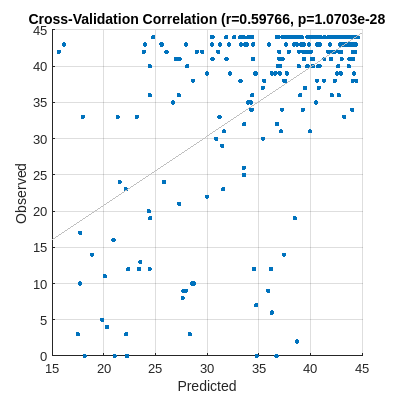

% Plot mean predicted out-of-fold values vs. observed values
clf;
scatter(mean(cv_results.all.pred_y.*-1,2), cv_results.all.obs_y.*-1, 50, '.'); lsline;
grid on; xlabel('Predicted'); ylabel('Observed'); title(['Cross-Validation Correlation (r=' num2str(cv_results.all.corr) ', p=' num2str(cv_results.all.corr_pval)]);
set(gcf, 'position', [0, 0, 400, 400]);

9. To evaluate *prediction* performance, load the cv_results.mat file from the output directory and view the contents.

- train_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be train_set(:, 1, 3), patients included in the training set have values equal to 1, and patients not in the training set for that fold for that repeat have values equal to 0.

- test_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be test_set(:, 1, 3), patients included in the test set have values equal to 1, and patients not in the test set for that fold for that repeat have values equal to 0.

- beta_0 - repeat-by-fold matrix of intercepts from the models fit to the training sets. Here, there was 1 repeat of 5-fold cross-validation, so beta_0 is a 1x5 array.

- vip - n_voxlels-by-repeat-by-fold matrix of VIP scores, analogous to the corresponding field in model_results

- opt_k - repeat-by-fold matrix of model dimensionalities determined by hyper-parameter optimization, analogous to the corresponding field in model_results

- avg - subfield containing model coefficients and performance estimates averaged across folds (note: median is used instead of mean if cfg.cv.summary_type = 'median')

- coeff - n_voxels-by-repeat-by-fold matrix of model coefficients, analogous to the corresponding field in model_results

- all - subfield containing out-of-fold predictions for all observations for each repeat, along with cross-validation test results (correlation of predicted and observed computed using average [across repeats] of out-of-fold predictions for all observations)

- pred_y - n_subjects-by-repeat-by-fold matrix of predicted behavioral scores for each test set in each fold and each repeat. For each fold within each repeat, patients that were in the training set have values equal to NaN, while patients in the test set have values equal to their predicted behavioral scores. 

- obs_y - same as pred_y, but with observed scores.

- explained - repeat-by-fold matrix of R-squared values for each test set computed using the explained variance score method. 

- r2_ss - repeat-by-fold matrix of R-squared values for each test set computed using the sum-of-squares method. 

- mse - repeat-by-fold matrix of mean squared error values for each test set. 

- corr - repeat-by-fold matrix of Pearson correlation values between predicted and observed scores for each test set.

- perm_pval - permutation p-value for mean (or median depending on value of cfg.cv.summary_type) cross-validation MSE

% Load cv_results to evaluate out-of-sample prediction
load(fullfile(cfg.out_dir, 'cv_results.mat'));
cv_results

cv_results = struct with fields:
    train_set: [282×5×5 double]
     test_set: [282×5×5 double]
       beta_0: [5×5 double]
          vip: [1966×5×5 double]
         optk: [5×5 double]
          avg: [1×1 struct]
        coeff: [1966×5×5 double]
          all: [1×1 struct]
       pred_y: [282×5×5 double]
        obs_y: [282×5×5 double]
    explained: [5×5 double]
        r2_ss: [5×5 double]
          mse: [5×5 double]
         corr: [5×5 double]


We can plot the explained variance for the held-out patients across folds of the cross-validation. The left plot shows the mean across folds for each repetition of the cross-validation. The right plot shows the distribution of R-squared values across all folds and repeats of the cross-validation (boxplot) along with the mean cross-validation R-squared (black dot) and the 95% CIs (red error bars) from the inerential model for comparison. 

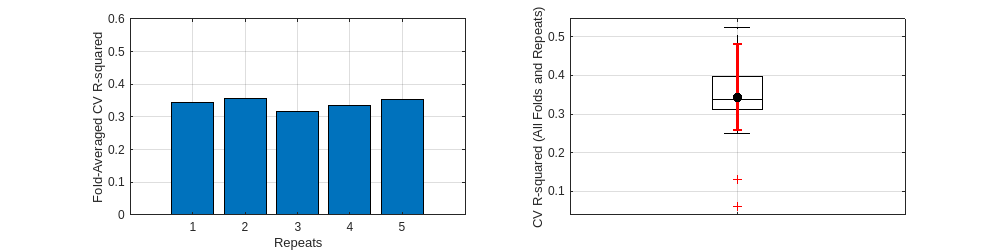

% Plot explained variance across folds
clf;
subplot(1,2,1); 
bar(cv_results.avg.r2_ss(:)); grid on;
hold on; ylabel('Fold-Averaged CV R-squared');
set(gca, 'YLim', [0, .6]); set(gca, 'XtickLabel', {'1', '2', '3', '4', '5'}); xlabel('Repeats')
subplot(1,2,2);
boxplot(cv_results.r2_ss(:), 'Colors', 'k');
hold on; ylabel('CV R-squared (All Folds and Repeats)');
set(gca, 'XtickLabel', '');hold on; 
errorbar(1, model_results.r2, model_results.r2-model_results.boot.r2_ci(1), model_results.boot.r2_ci(2)-model_results.r2, 'Color', 'r', 'LineWidth', 2);
plot(mean(cv_results.r2_ss(:)), 'Marker', '.', 'MarkerSize', 25, 'MarkerEdgeColor', 'k'); set(gcf, 'position', [0, 0, 1000, 250]); grid on;

9. Save explanatory model coefficients as .edge and .node files (for ball and stick representations). Files containing model coefficients will be saved in the output directory specified by cfg.out_dir. If bootstrapping and/or permutation testing was performed for model weights, then result images will be saved into sub-folders named "Bootstrap_Result_Images" and "Permutation_Result_Images", respectively. 

% Map model coefficients back to the in-brain voxels of the 3D MNI volume using MATLAB NIFTI I/O functions
disp('Saving beta weight maps as .node and .edge files...');

Saving beta weight maps as .node and .edge files...


write_model_weights_connectome(model_results);
disp('Done')

Done
